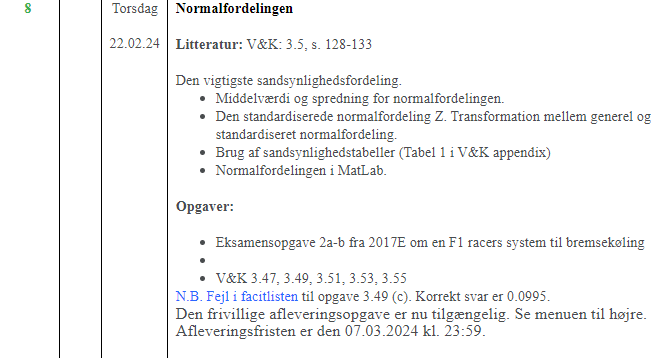

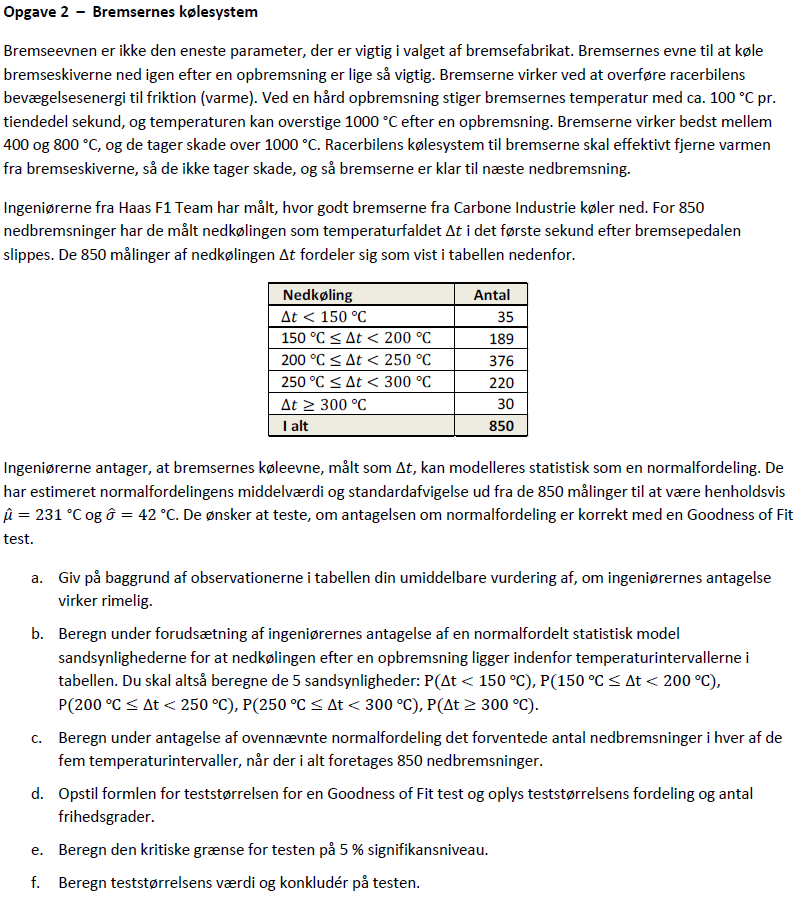

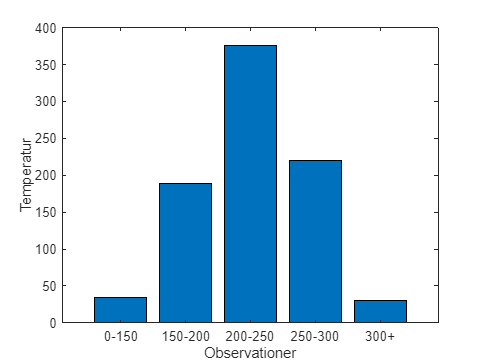

clc; clear;

% Opgave a)
% Ja, antagelsen er rimelig, da n er stor, og:

% Data fra opgaven
sigma = 42;
mu = 231;

% Antal observeringer i tabellen
obs = 1:1:5;
delta_ts = [35, 189, 376, 220, 30];

% Bar plot og dist plot
X = categorical({'0-150','150-200','200-250','250-300', '300+'});
X2 = reordercats(X,{'0-150','150-200','200-250','250-300', '300+'});
Y = delta_ts;

NormDist = makedist("Normal","mu", mu,"sigma", sigma);

PD = pdf(NormDist, linspace(0,400));

figure
bar(X,Y)
ylabel("Temperatur")
xlabel("Observationer")

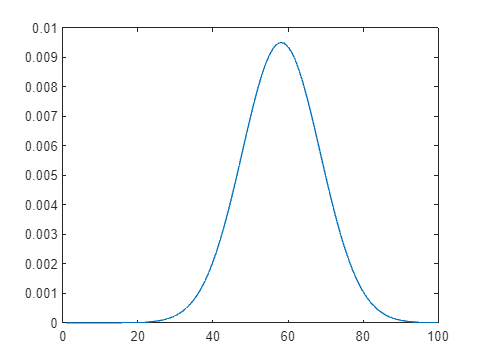


figure
plot(PD)

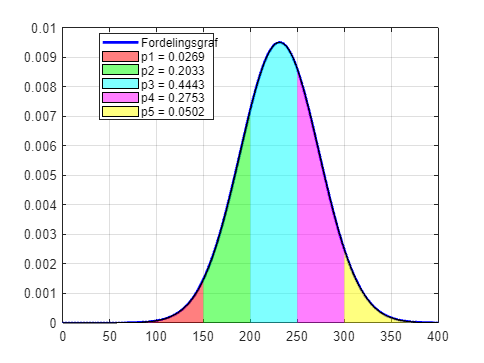

      Interval       Sandsynligheder    I procent
    _____________    _______________    _________

    "-inf -> 150"        0.0269         " 2.69%" 
    "150 til 200"        0.2033         "20.33%" 
    "200 til 250"        0.4443         "44.43%" 
    "250 til 300"        0.2753         "27.53%" 
    "300 -> inf"         0.0502         " 5.02%" 
    "Sum"                     1         "  100%" 



ans = struct with fields:
    sshs: [0.0269 0.2033 0.4443 0.2753 0.0502]


% Opgave b)

IntervalNormal(mu, sigma, 0, 400, [150, 200, 250, 300])


p1 = normcdf(150, mu, sigma)

p1 = 0.0269

p2 = normcdf(200, mu, sigma) - p1

p2 = 0.2033

p3 = normcdf(250, mu, sigma) - normcdf(200, mu, sigma)

p3 = 0.4443

p4 = normcdf(300, mu, sigma) - normcdf(250, mu, sigma)

p4 = 0.2753

p5 = 1 - normcdf(300, mu, sigma)

p5 = 0.0502

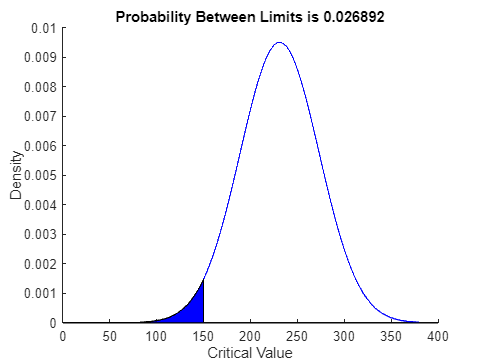

ans = 0.0269

normspec([0,150], mu, sigma, "inside")

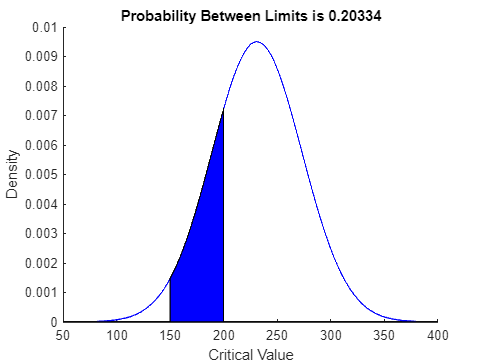

ans = 0.2033

normspec([150,200], mu, sigma, "inside")

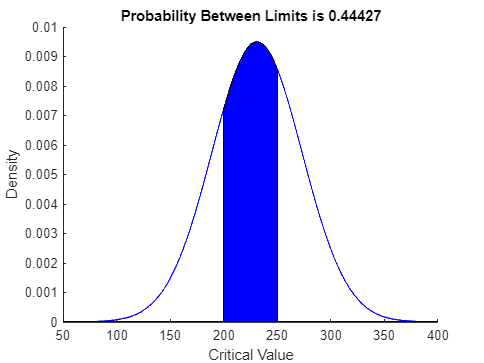

ans = 0.4443

normspec([200,250], mu, sigma, "inside")

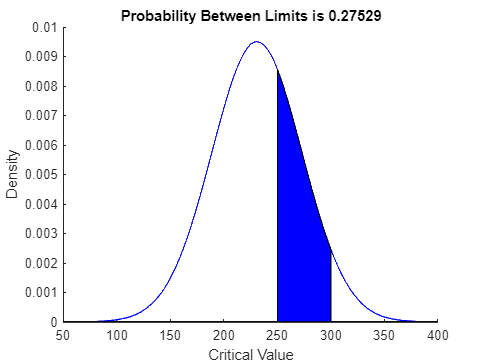

ans = 0.2753

normspec([250,300], mu, sigma, "inside")

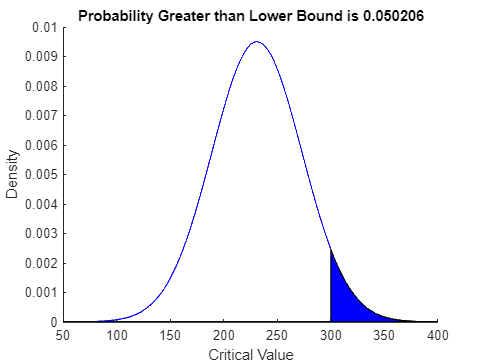

ans = 0.0502

normspec([300, inf], mu, sigma, "inside")